# Thermoeconomic Analysis of a Cogeneration Gas Turbine (CGAM)

This Live Script makes a Thermoeconomic Analysis of an Cogeneration Gas Turbine Cycle, using the TaesLab functions.

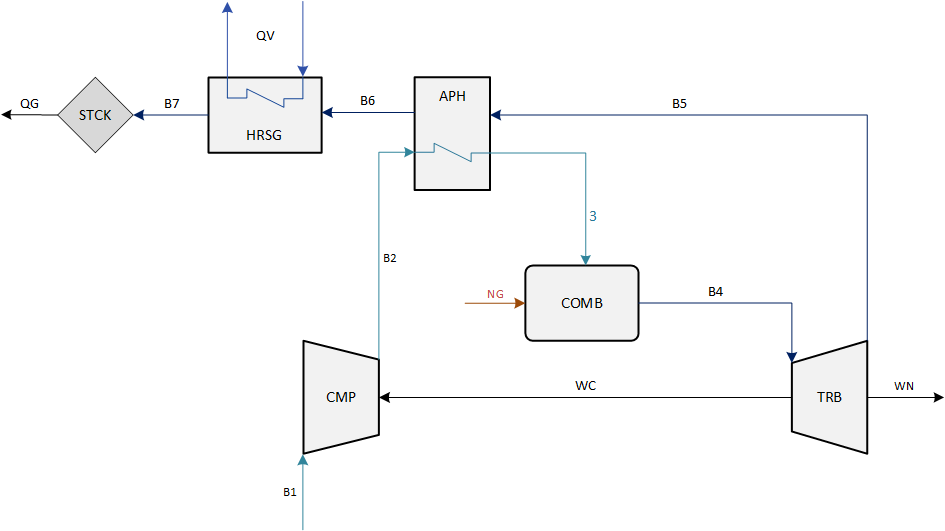

### 1. Read the data model file

This function reads the data model file and loads it as a MATLAB object 

model=ThermoeconomicModel('cgam_model.json','CostTables','ALL','Summary','STATES');

INFO: cDataModel. Productive Structure is valid
INFO: cDataModel. Format Definition is valid
INFO: cDataModel. Exergy values [REF] are valid
INFO: cDataModel. Exergy values [T1180] are valid
INFO: cDataModel. Exergy values [ETG87] are valid
INFO: cDataModel. Exergy values [ECMP84] are valid
INFO: cDataModel. Exergy values [RP8] are valid
INFO: cDataModel. Exergy values [PINCH15] are valid
INFO: cExergyData. Process HRSG is not active
INFO: cDataModel. Exergy values [CGAMR] are valid
INFO: cExergyData. Process APH is not active
INFO: cDataModel. Exergy values [noAPH] are valid
INFO: cDataModel. Waste Definition is valid
INFO: cDataModel. Resources Cost sample [Base] is valid
INFO: cDataModel. Resources Cost sample [CGAMR] is valid
INFO: cDataModel. Data model cgam_model is valid
INFO: cThermoeconomicModel. Set reference state REF
INFO: cThermoeconomicModel. Set resource sample Base
INFO: cThermoeconomicModel. Set active waste QG
INFO: cThermoeconomicModel. Recycle is not active
INFO: cT

#### **Show the model properties**

model.setDebug(false);
model.showProperties;

 
              State: 'REF'
     ReferenceState: 'REF'
     ResourceSample: 'Base'
         CostTables: 'ALL'
    DiagnosisMethod: 'WASTE_EXTERNAL'
        ActiveWaste: 'QG'
            Summary: 'STATES'
          Recycling: 'false'
              Debug: 'false'
     IsResourceCost: 'true'
        IsDiagnosis: 'false'
          IsSummary: 'true'
            IsWaste: 'true'



#### **Show **the** data model**

ShowResults(model.DataModel)


Flows Data

 key   type      
———————————————————
 NG    RESOURCE  
 B1    RESOURCE  
 B2    INTERNAL  
 B3    INTERNAL  
 B4    INTERNAL  
 B5    INTERNAL  
 B6    INTERNAL  
 B7    INTERNAL  
 WC    INTERNAL  
 WN    OUTPUT    
 QV    OUTPUT    
 QG    WASTE     


Processes Data

 key    type          fuel    product  
—————————————————————————————————————————
 COMB   PRODUCTIVE    NG+B3   B4       
 CMP    PRODUCTIVE    WC      B2-B1    
 TRB    PRODUCTIVE    B4-B5   WC+WN    
 APH    PRODUCTIVE    B5-B6   B3-B2    
 HRSG   PRODUCTIVE    B6-B7   QV       
 STCK   DISSIPATIVE   B7      QG       


Exergy Data

 key          REF       T1180       ETG87      ECMP84         RP8     PINCH15       CGAMR       noAPH 
————————————————————————————————————————————————————————————————————————————————————————————————————————
 NG        72.465      73.327        73.6      73.297      72.283      72.465      72.465     109.913 
 B1             0           0           0           0           0  

### **2. **Show Results for Reference state

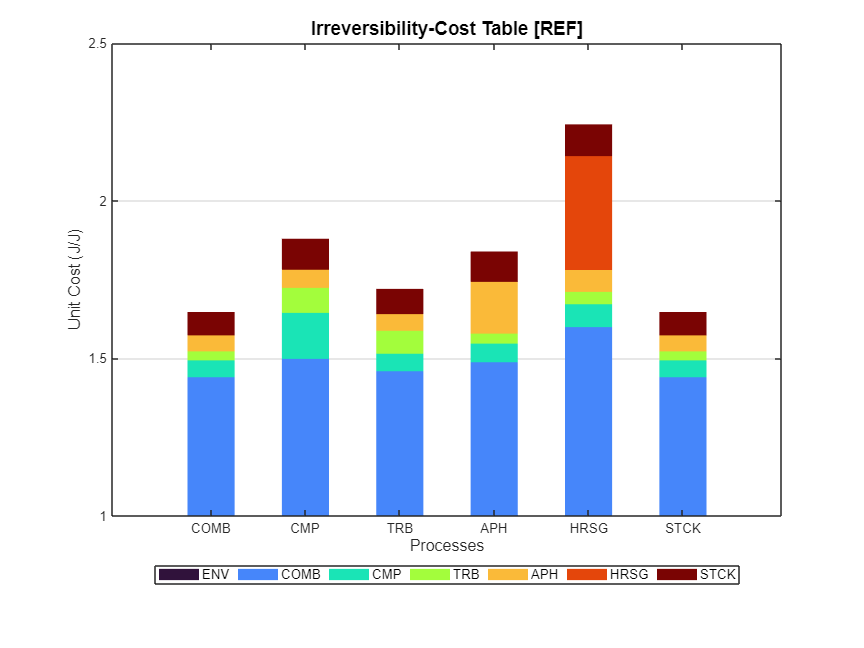

ShowGraph(model);

**Select the table to show**

tables=string(ListOfTables(model));
ShowResults(model,'Table',char(tables(10)));


Flows Exergy Cost - REF

Key         B(MW)      B*(MW)    Bin*(MW)     Br*(MW)      k*(J/J)    kin*(J/J)     kr*(J/J)
—————————————————————————————————————————————————————————————————————————————————————————————
NG         72.465      72.465      72.465       0.000       1.0000       1.0000       0.0000
B1          0.000       0.000       0.000       0.000       0.0000       0.0000       0.0000
B2         28.651      53.837      51.022       2.814       1.8790       1.7808       0.0982
B3         50.339      93.719      88.815       4.903       1.8618       1.7643       0.0974
B4        102.530     168.868     161.280       7.588       1.6470       1.5730       0.0740
B5         38.810      63.920      61.048       2.872       1.6470       1.5730       0.0740
B6         14.784      24.349      23.255       1.094       1.6470       1.5730       0.0740
B7          2.122       3.495       3.338       0.157       1.6470       1.5730       0.0740
WC         31.105      53.512      51.022  

### 3. Thermoeconomic Diagnosis

Select the state to compare with reference state and show results

states=model.StateNames;
model.CurrentState=char(states(2));
dg=model.thermoeconomicDiagnosis;
ShowResults(dg,'Table',cType.Tables.DIAGNOSIS);


Diagnosis Summary - T1180

Key         MF(MW)      ΔI(MW)      ΔR(MW)     ΔPt(MW)     MF*(MW)     MR*(MW)    ΔPt*(MW)
———————————————————————————————————————————————————————————————————————————————————————————
COMB        0.3000      0.4870      0.0000      0.0000      0.3968      0.0000      0.0000
CMP        -0.0013      0.0720      0.0000      0.0000     -0.0021      0.0000      0.0000
TRB         0.0387      0.0790      0.0000      0.0000      0.0613      0.0000      0.0000
APH         0.0195     -0.0130      0.0000      0.0000      0.0309      0.0000      0.0000
HRSG       -0.0081      0.0282      0.0000      0.1008     -0.0128      0.0000      0.2277
STCK        0.0000      0.0000      0.1080      0.0000      0.0000      0.1603      0.0000
ENV         0.3488      0.6532      0.1080      0.1008      0.4740      0.1603      0.2277



dg.summaryDiagnosis;


Fuel Impact:          0.8620 (MW)
Technical Saving:     0.6360 (MW)



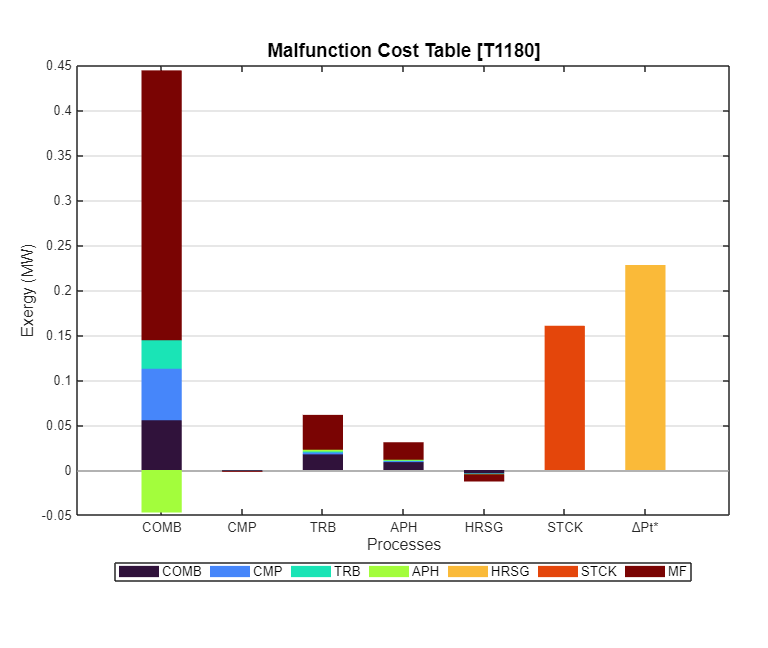

ShowGraph(dg);

### 4. Recycling Analysis

Change the waste allocation method, for Active Waste

model.setRecycling(true);
model.setState('CGAMR');
model.setWasteType('IRREVERSIBILITY');
model.setWasteRecycled(0.5);

#### Show Waste Allocation Graph

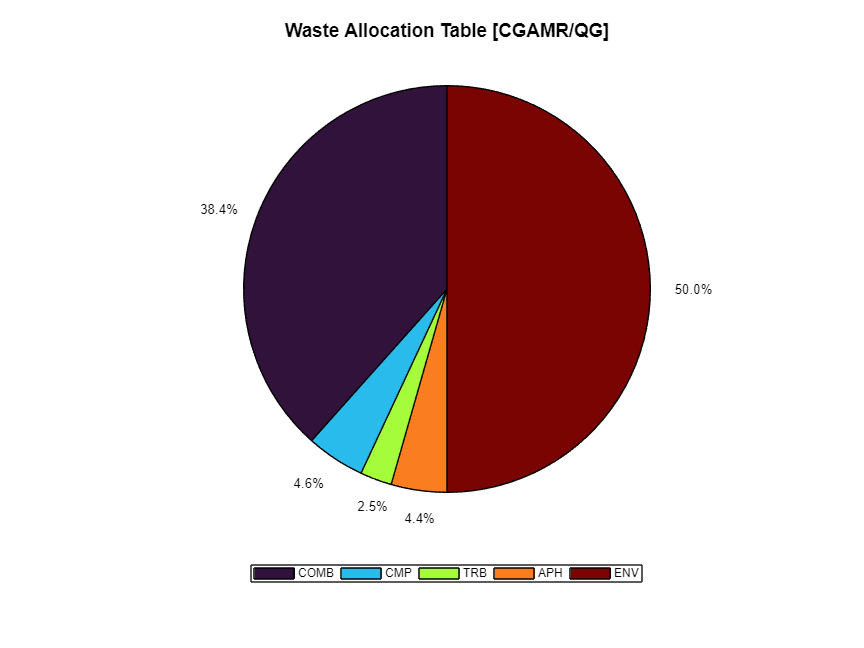

ShowGraph(model,'Graph',cType.Tables.WASTE_ALLOCATION);

ShowResults(model,'Table',cType.Tables.PROCESS_UNIT_COST);


Process Unit Exergy Cost - CGAMR

Key        kP*(J/J)    kin*(J/J)    kex*(J/J)     kF*(J/J)     kR*(J/J)       k(J/J)
—————————————————————————————————————————————————————————————————————————————————————
COMB         1.8648       1.5730       0.2918       1.4707       0.1033       1.1977
CMP          2.1683       1.7808       0.3875       1.9560       0.0447       1.0857
TRB          1.9560       1.6403       0.3157       1.8648       0.0114       1.0428
APH          2.1222       1.7426       0.3796       1.8648       0.0563       1.1078
HRSG         0.0000       0.0000       0.0000       0.0000       0.0000       1.0000
STCK         1.8648       1.5730       0.2918       1.8648       0.0000       1.0000



#### **Analize the **potential** saving of combustion gases recycling**

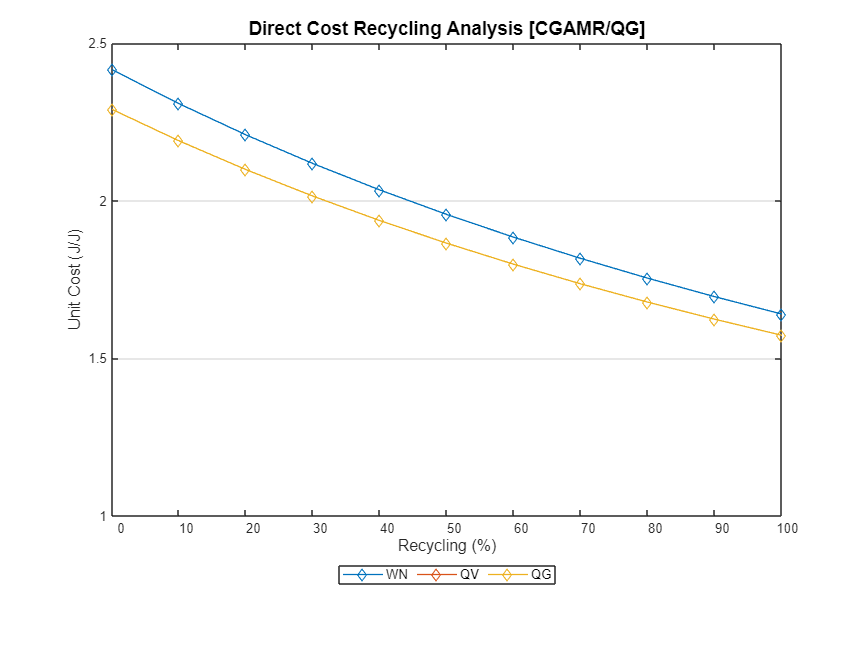

wr=model.wasteAnalysis;
ShowGraph(wr,'Graph',cType.Tables.WASTE_RECYCLING_DIRECT);

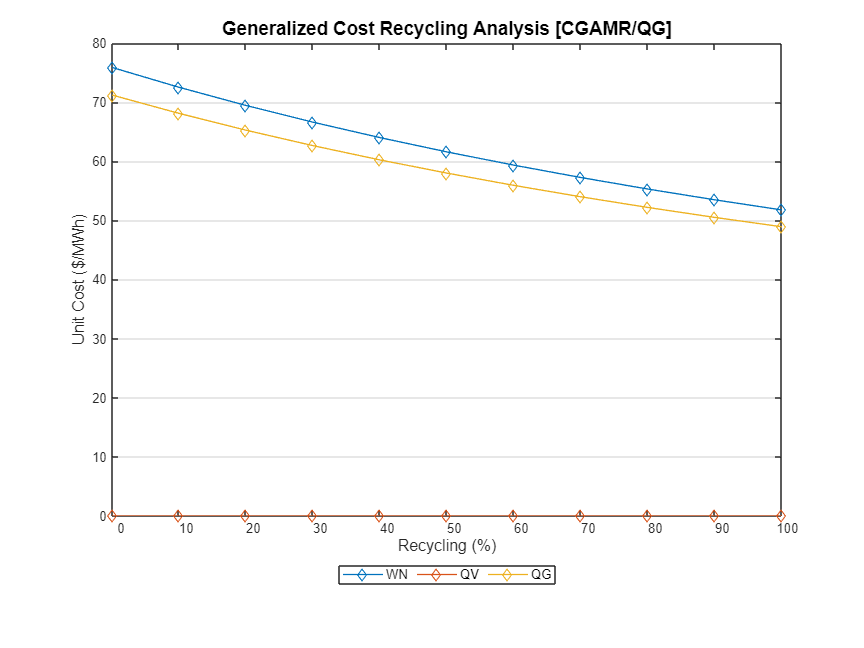

ShowGraph(wr,'Graph',cType.Tables.WASTE_RECYCLING_GENERAL);

**Restart recycling parameters**

model.setRecycling(false);
model.setWasteRecycled(0.0);

### 5. Modify Data Model

Use `ImportData `function to add a new state and a new resource state from exernal files

#### Create a new state

Use external file `ExergyData.csv `to create a new plant state `Test.` (Simulate an inefficiency in APH) 

tbl=ImportData('ExergyData.csv');
val=tbl.getColumnValues(1);
model.addExergyData('Test',val);
model.showResults(cType.Tables.FLOW_GENERAL_COST);


Flows Generalized Cost - [Test/Base]

Key         B(MW)       C($/h)     Cin($/h)      Cz($/h)      Cr($/h)    c($/MWh)  cin($/MWh)   cz($/MWh)   cr($/MWh)
——————————————————————————————————————————————————————————————————————————————————————————————————————————————————————
NG         82.457      2473.71      2473.71         0.00         0.00      30.000      30.000       0.000       0.000
B1          0.000         0.00         0.00         0.00         0.00       0.000       0.000       0.000       0.000
B2         30.735      1876.14      1694.84       111.75        69.55      61.043      55.144       3.636       2.263
B3         51.015      3113.39      2826.55       168.50       118.34      61.029      55.406       3.303       2.320
B4        110.079      5657.66      5300.26       172.10       185.30      51.396      48.150       1.563       1.683
B5         43.232      2221.97      2081.60        67.59        72.78      51.396      48.150       1.563       1.683
B6         19.72

#### Create a new resource sample

Use external files` ResourceFlow.csv` and `ResourceProcess.csv` to create a new resource sample

tbl=ImportData('ResourceFlows.csv');
rval=tbl.getColumnData(2);
tbl=ImportData('ResourceProcesses.csv');
pval=tbl.getColumnValues(2);
model.addResourceData('Test',rval,pval);
model.showResults(cType.Tables.FLOW_GENERAL_COST);


Flows Generalized Cost - [Test/Test]

Key         B(MW)       C($/h)     Cin($/h)      Cz($/h)      Cr($/h)    c($/MWh)  cin($/MWh)   cz($/MWh)   cr($/MWh)
——————————————————————————————————————————————————————————————————————————————————————————————————————————————————————
NG         82.457      2885.99      2885.99         0.00         0.00      35.000      35.000       0.000       0.000
B1          0.000         0.00         0.00         0.00         0.00       0.000       0.000       0.000       0.000
B2         30.735      2175.00      1977.31       116.81        80.88      70.766      64.334       3.801       2.631
B3         51.015      3611.48      3297.64       176.23       137.62      70.793      64.641       3.454       2.698
B4        110.079      6579.04      6183.63       179.93       215.48      59.767      56.174       1.635       1.958
B5         43.232      2583.83      2428.54        70.66        84.63      59.767      56.174       1.635       1.958
B6         19.72

#### Show the actual model parameters 

Show the model parameters

model.showProperties;

 
              State: 'Test'
     ReferenceState: 'REF'
     ResourceSample: 'Test'
         CostTables: 'ALL'
    DiagnosisMethod: 'WASTE_EXTERNAL'
        ActiveWaste: 'QG'
            Summary: 'STATES'
          Recycling: 'false'
              Debug: 'false'
     IsResourceCost: 'true'
        IsDiagnosis: 'true'
          IsSummary: 'true'
            IsWaste: 'true'



#### **Update the model and show the data model**

model.updateDataModel;
showResults(model.DataModel);


Flows Data

 key   type      
———————————————————
 NG    RESOURCE  
 B1    RESOURCE  
 B2    INTERNAL  
 B3    INTERNAL  
 B4    INTERNAL  
 B5    INTERNAL  
 B6    INTERNAL  
 B7    INTERNAL  
 WC    INTERNAL  
 WN    OUTPUT    
 QV    OUTPUT    
 QG    WASTE     


Processes Data

 key    type          fuel    product  
—————————————————————————————————————————
 COMB   PRODUCTIVE    NG+B3   B4       
 CMP    PRODUCTIVE    WC      B2-B1    
 TRB    PRODUCTIVE    B4-B5   WC+WN    
 APH    PRODUCTIVE    B5-B6   B3-B2    
 HRSG   PRODUCTIVE    B6-B7   QV       
 STCK   DISSIPATIVE   B7      QG       


Exergy Data

 key          REF       T1180       ETG87      ECMP84         RP8     PINCH15       CGAMR       noAPH        Test 
————————————————————————————————————————————————————————————————————————————————————————————————————————————————————
 NG        72.465      73.327        73.6      73.297      72.283      72.465      72.465     109.913      82.457 
 B1             0           0  

### 6. Show results for Test study case

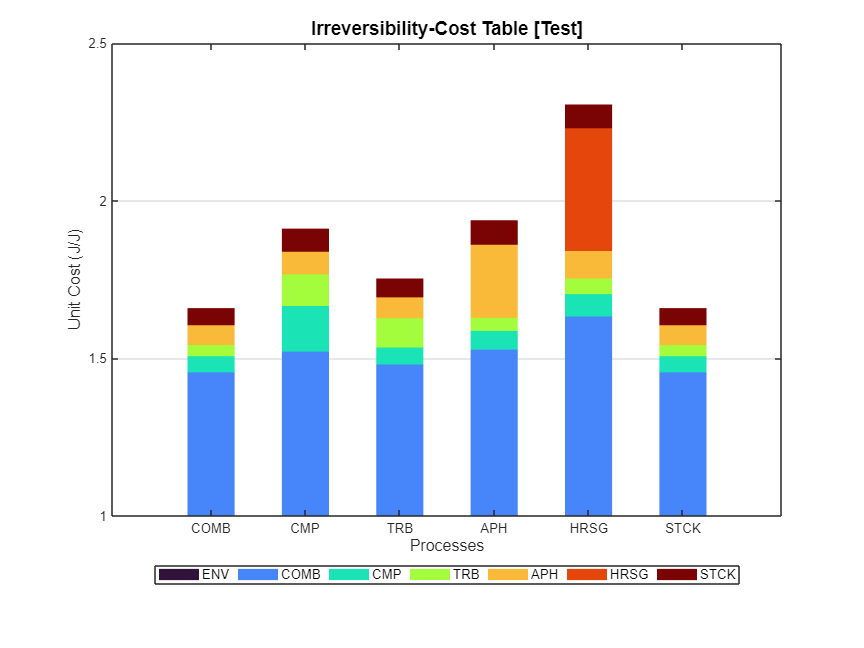

ShowGraph(model);

ShowResults(model);


Flows Definition Table - Test

  Id Key  From     To       Type      
———————————————————————————————————————
   1 NG   ENV_R1   COMB_F1  RESOURCE  
   2 B1   ENV_R2   CMP_P1   RESOURCE  
   3 B2   CMP_P1   APH_P1   INTERNAL  
   4 B3   APH_P1   COMB_F1  INTERNAL  
   5 B4   COMB_P1  TRB_F1   INTERNAL  
   6 B5   TRB_F1   APH_F1   INTERNAL  
   7 B6   APH_F1   HRSG_F1  INTERNAL  
   8 B7   HRSG_F1  STCK_F1  INTERNAL  
   9 WC   TRB_P1   CMP_F1   INTERNAL  
  10 WN   TRB_P1   ENV_O1   OUTPUT    
  11 QV   HRSG_P1  ENV_O2   OUTPUT    
  12 QG   STCK_P1  ENV_W1   WASTE     


Productive Groups Definition Table - Test

  Id Key      Definition  Type      
—————————————————————————————————————
   1 COMB_F1  NG+B3       FUEL      
   2 COMB_P1  B4          PRODUCT   
   3 CMP_F1   WC          FUEL      
   4 CMP_P1   B2-B1       PRODUCT   
   5 TRB_F1   B4-B5       FUEL      
   6 TRB_P1   WC+WN       PRODUCT   
   7 APH_F1   B5-B6       FUEL      
   8 APH_P1   B3-B2       PRODUCT   
   9 

### 7. Show Summary Result

Show the summary results.

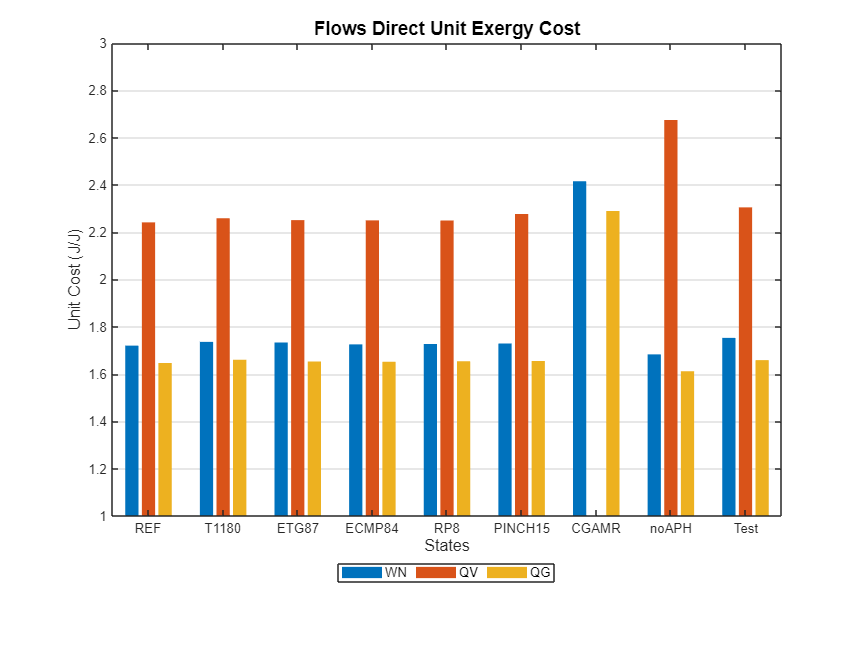

res=model.summaryResults;
ShowGraph(res);

**Select the summary table to show**

stables=string(ListOfTables(res));
ShowResults(res,'Table',char(stables(2)));


Process Unit Consumption (J/J) - SUMMARY

 key             REF       T1180       ETG87      ECMP84         RP8     PINCH15       CGAMR       noAPH        Test
—————————————————————————————————————————————————————————————————————————————————————————————————————————————————————
 COMB         1.1977      1.2007      1.1958      1.1975      1.1955      1.1977      1.1977      1.3575      1.2125
 CMP          1.0857      1.0856      1.0856      1.0916      1.0873      1.0857      1.0857      1.0856      1.0856
 TRB          1.0428      1.0434      1.0468      1.0428      1.0422      1.0428      1.0428      1.0428      1.0549
 APH          1.1078      1.1087      1.1075      1.1070      1.1096      1.1078      1.1078      1.0000      1.1590
 HRSG         1.3611      1.3603      1.3614      1.3619      1.3597      1.3754      1.0000      1.6589      1.3891
 STCK         1.0000      1.0000      1.0000      1.0000      1.0000      1.0000      1.0000      1.0000      1.0000
 ENV          1.8438